# 2

function that calculates fourier series is defined in FseriesFunc.m 

our function returns A0 ,An and Bn which are the coefficients of fourier series:

- *[A0,An,Bn] = FseriesFunc(Num,P,a,Nshow,draw)*

- *here draw is signal to allow ploting the function*

# 2.2

fourier series coefficients are displayed below

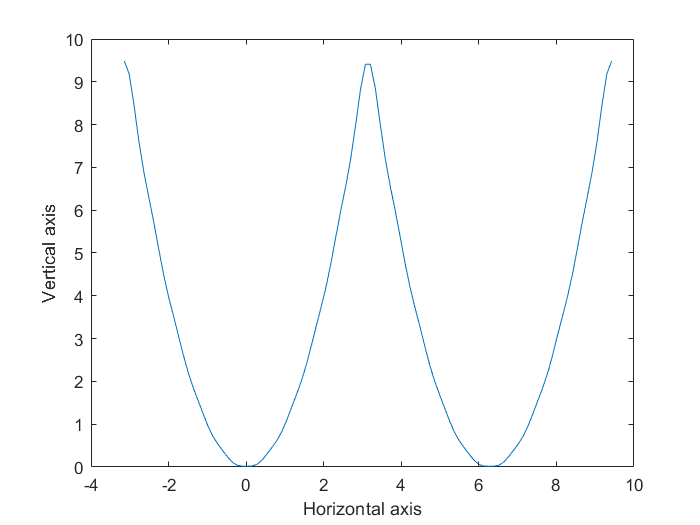

[A0,An,Bn]=FseriesFunc(10,2,2,5,1);

disp(A0);

    3.2899



disp(An);

   -4.0000
    1.0000
   -0.4444
    0.2500
   -0.1600



disp(Bn);

   1.0e-15 *

    0.0353
    0.1767
   -0.1767
   -0.0707
    0.4241



# 2.3

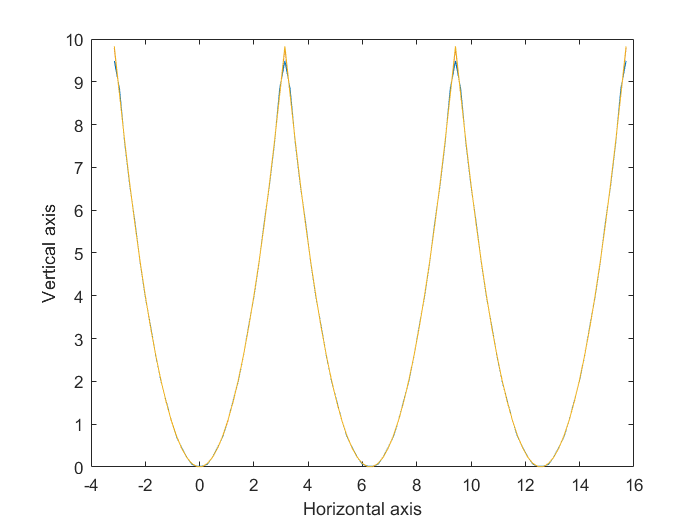

[A0,An,Bn]=FseriesFunc(10,3,2,5,1);
hold on;
[A01,An1,Bn1]=FseriesFunc(50,3,2,5,1);
hold on;
[A02,An2,Bn2]=FseriesFunc(100,3,2,5,1);
hold off;

### *as it is obvious the more we increse the Num value we get a more percise plot of x^2*

## this happens because when we increase the Num more expressions would be calculated and matlab has more detail about the figure it is trying to draw

# **2.4**

**first the paper calculations:**

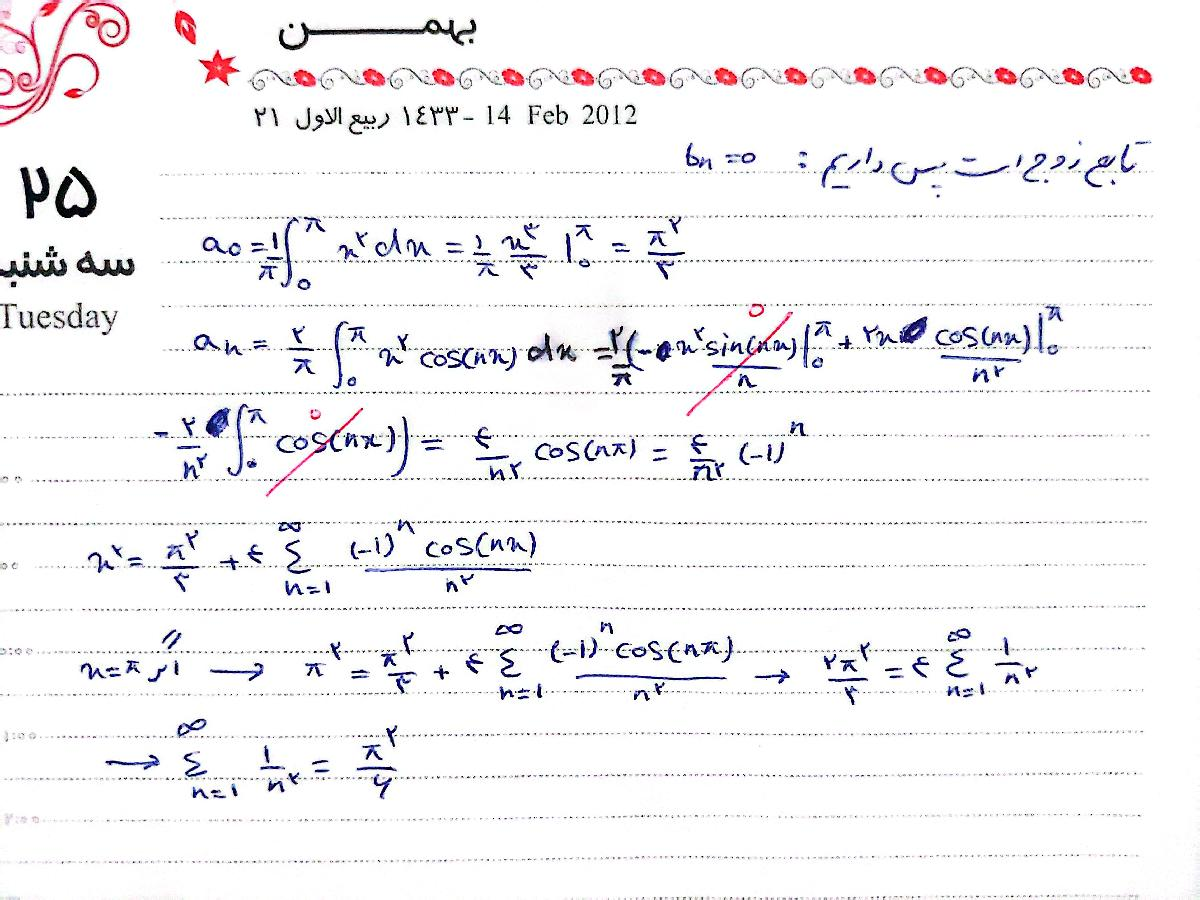

we use pi as our x

chosen_x=pi;
[A0,An,Bn]=FseriesFunc(100,3,2,20,0);
code_val=A0;
for i=1:length(An)
    code_val=code_val+An(i)*cos(i*chosen_x)+Bn(i)*sin(i*chosen_x);
end
disp((code_val-(pi.^2/3))./4)

    1.5962



the value is close but it is not the same because we are using 100 for num instead of infinity

# 2.5

function that calculates harmonic series is defined in harmonic_analisys.m 

our function returns a0 ,an and bn which are the coefficients of harmonic series:

- *[a0,an,bn]=harmonic_analisys(x,fx,N)*

- *function also plots harmonic series against the x that has been passed in*

# *2.5.2*

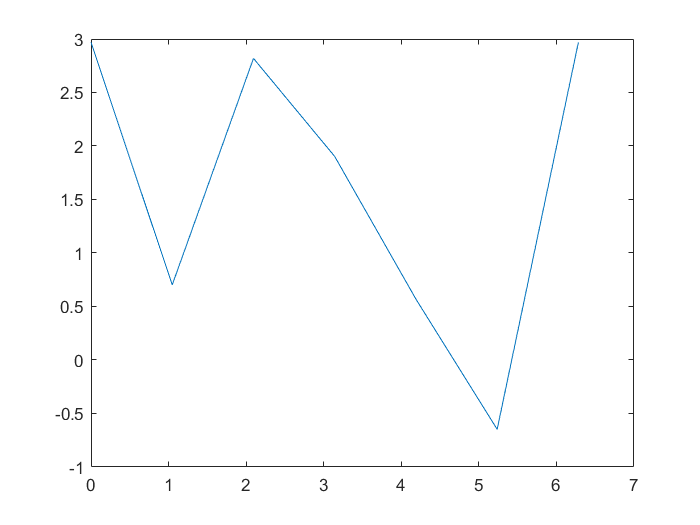

%%z
x=linspace(0,2*pi,7);
fx=[1 1.4 1.9 1.7 1.5 1.2 1];
N=4;
[a0,an,bn]=harmonic_analisys(x,fx,N);

disp(a0);

    1.3857



disp(an);

   -0.2000
    0.7000
    0.7333
    0.3500



disp(bn);

    1.0392
   -0.1732
   -0.0000
    0.0866

